load('UandV_arrays2.mat')
load("CFD_confined_TSR_1_1.mat")
rt = 2.042;
Uinf = 0.91;
lam = 1.1;
%lam = 1.9;
Omega = lam*Uinf/rt;
syms t;
Ry2 = [cosd(t) sind(t); -sind(t) cosd(t)];
GC = struct;
GC.alphaP = 6;
GC.lambda = lam;
num = length(theta)
Xrots = struct;
Yrots = struct;

for k=1:num
    alpha = theta(k);
    XY = [X(:) Y(:)];
    XYRy2 = XY*Ry2;
    res = subs(XYRy2,t,-alpha);
    res = double(res);
    Xrot3 = reshape(res(:,1), size(X,1), []);
    Yrot3 = reshape(res(:,2), size(Y,1), []);
    Xrots(k).Xrot3 = Xrot3;
    Yrots(k).Yrot3 = Yrot3;
end

k = 25

k = 25

alpha = theta(k);
Xrot3 = Xrots(k).Xrot3;
Yrot3 = Yrots(k).Yrot3;
Yrot4 = Yrot3-2.042;
u4 = Us(k).u4;
v4 = Us(k).v4;
foiltest = plot_foil(theta(k),1);
XYRy2 = Ry2*foiltest';
res = subs(XYRy2,t,alpha);
foiltest2(:,:) = res';

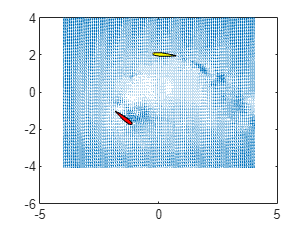

%quiver(Xrot3,Yrot4,u4,v4)
quiver(X,Y,u4,v4);
% xlim([-2.5 1.5])
% ylim([-1.5 1.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
fill(foiltest2(:,1),foiltest2(:,2),'y')
hold off

[x,y] = meshgrid(1:20,1:20)

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     2     3     4    

y =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7
     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8
     9     9     9     9    

x2 = x;
y2 = y;
h = 1;
tic
for i = 1:(length(x))^2
    if h>length(x)
        h =1;
    end
    j = ceil(i/length(x));
    T3 = [x(h,j)';y(h,j)'];
    XYRy2 = Ry2*T3;
    res = subs(XYRy2,t,alpha);
    x2(h,j) = res(1);
    y2(h,j) = res(2);
    h = h+1;
end
toc

Elapsed time is 2.828624 seconds.


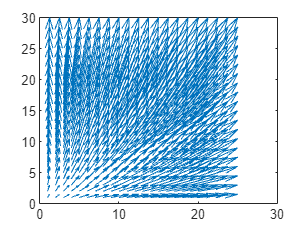

U = 0.25*x;
V = 0.5*y;
quiver(x,y,U,V,0)

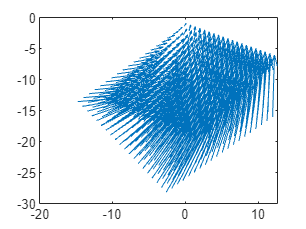

quiver(x2,y2,U,V,0)

[Xq,Yq] = meshgrid(X,Y)

Xq =    -4.0000   -3.9192   -3.8384   -3.7576   -3.6768   -3.5960   -3.5152   -3.4343   -3.3535   -3.2727   -3.1919   -3.1111   -3.0303   -2.9495   -2.8687   -2.7879   -2.7071   -2.6263   -2.5455   -2.4646   -2.3838   -2.3030   -2.2222   -2.1414   -2.0606   -1.9798   -1.8990   -1.8182   -1.7374   -1.6566   -1.5758   -1.4949   -1.4141   -1.3333   -1.2525   -1.1717   -1.0909   -1.0101   -0.9293   -0.8485   -0.7677   -0.6869   -0.6061   -0.5253   -0.4444   -0.3636   -0.2828   -0.2020   -0.1212   -0.0404
   -4.0000   -3.9192   -3.8384   -3.7576   -3.6768   -3.5960   -3.5152   -3.4343   -3.3535   -3.2727   -3.1919   -3.1111   -3.0303   -2.9495   -2.8687   -2.7879   -2.7071   -2.6263   -2.5455   -2.4646   -2.3838   -2.3030   -2.2222   -2.1414   -2.0606   -1.9798   -1.8990   -1.8182   -1.7374   -1.6566   -1.5758   -1.4949   -1.4141   -1.3333   -1.2525   -1.1717   -1.0909   -1.0101   -0.9293   -0.8485   -0.7677   -0.6869   -0.6061   -0.5253   -0.4444   -0.3636   -0.2828   -0.2020   -0.1212   -

Yq =     -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4  

XY = [X(:) Y(:)]

XY =    -4.0000   -4.0000
   -3.9192   -4.0000
   -3.8384   -4.0000
   -3.7576   -4.0000
   -3.6768   -4.0000
   -3.5960   -4.0000
   -3.5152   -4.0000
   -3.4343   -4.0000
   -3.3535   -4.0000
   -3.2727   -4.0000


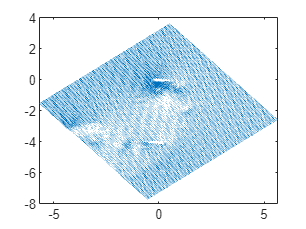

XYRy2 = XY*Ry2;
res = subs(XYRy2,t,-alpha);
res = double(res);
Xrot3 = reshape(res(:,1), size(X,1), []);
Yrot3 = reshape(res(:,2), size(Y,1), []);
Yrot4 = Yrot3-2.042;
quiver(Xrot3,Yrot4,Us(k).u3,Us(k).v3)

[curlz,cav] = curl(Xrot3,Yrot4,Us(k).u3,Us(k).v3);
max(max(curlz))

ans = 43.6460

min(min(curlz))

ans = -31.9731

pcolor(Xrot3,Yrot4,curlz)
shading interp
map = [1 0 0;1 1 1;0 0 1]

map =      1     0     0
     1     1     1
     0     0     1


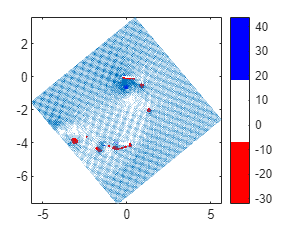

colormap(map)
colorbar
hold on
quiver(Xrot3,Yrot4,Us(k).u3,Us(k).v3)
hold off

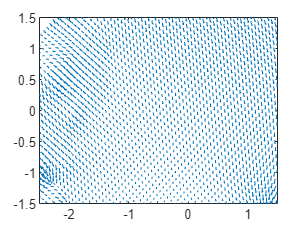

quiver(Xrot3,Yrot4,u4,v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])